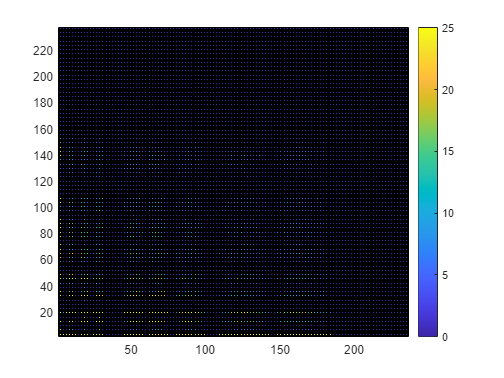

%%%%数据映射%%%%%
VarName1=Untitled(:,1);
VarName2=Untitled(:,2);
VarName3=Untitled(:,3);
VarName4=Untitled(:,4);
peakdata=oldpeakdata;
data=[VarName1,VarName2,VarName3,VarName4];
X=tabulate(VarName2);
X=X(:,1);
for i=1:4
    for j=1:length(VarName1)
        data(j,i)=find(X==data(j,i));
    end
end
for i=1:9
    peakdata(i,1)=find(X==peakdata(i,1));
    peakdata(i,2)=find(X==peakdata(i,2));
    peakdata(i,3)=find(X==peakdata(i,3));
    peakdata(i,4)=find(X==peakdata(i,4));
end
VarName1=data(:,1);
VarName2=data(:,2);
VarName3=data(:,3);
VarName4=data(:,4);
midu=[];
m=0;
zuobiao=[VarName1,VarName2];
for i=1:length(X)
    for j=1:length(X)
        for k=1:length(VarName1)
            if zuobiao(k,1)-i==0 && zuobiao(k,2)-j==0
                m=m+1;
            end
        end
        row=[i j m];
        midu=[midu;row];
        m=0;
    end
end
juzhen=zeros(237);
k=1;
for i=1:237
    for j=1:237
        juzhen(i,j)=midu(k,3);
        k=k+1;
    end
end

%%%数据清洗%%%


cleaned=zeros(237);
for i=2:8
    for j=2:8
        a=min((peakdata(i+1,1)-peakdata(i,1)),(peakdata(i,1)-peakdata(i-1,1)))/2-1;
        b=min((peakdata(j+1,2)-peakdata(j,2)),(peakdata(j,2)-peakdata(j-1,2)))/2-1;
        if a>b
            c=sqrt(a^2-b^2);
            for m=1:237
                for n=1:237
                    distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(j,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(j,2))^2);
                    if distance<=2*a
                        cleaned(m,n)=juzhen(m,n);

                    end
                end
            end
        end

        if a<=b
            c=sqrt(b^2-a^2);
            for m=1:237
                for n=1:237
                    distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(j,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(j,2)-c)^2);
                    if distance<=2*b
                        cleaned(m,n)=juzhen(m,n);
                    end
                end
            end
        end
    end
end

%bianjie zuo
for i=2:8
    a=min((peakdata(i+1,1)-peakdata(i,1)),(peakdata(i,1)-peakdata(i-1,1)))/2-1;
    b1=(peakdata(2,2)-peakdata(1,2))/2-1;
    b2=(peakdata(9,2)-peakdata(8,2))/2-1;
    if a>b1
        c=sqrt(a^2-b1^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(1,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(1,2))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b1
        c=sqrt(b1^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(1,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(1,2)-c)^2);
                if distance<=2*b1
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie you
    if a>b2
        c=sqrt(a^2-b2^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(9,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(9,2))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b2
        c=sqrt(b2^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(9,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(9,2)-c)^2);
                if distance<=2*b2
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie xia
    a=min((peakdata(i+1,2)-peakdata(i,2)),(peakdata(i,2)-peakdata(i-1,2)))/2-1;
    b1=(peakdata(2,1)-peakdata(1,1))/2-1;
    b2=(peakdata(9,1)-peakdata(8,1))/2-1;
    if a>b1
        c=sqrt(a^2-b1^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)+c))^2+(m-peakdata(1,1))^2)+sqrt((n-(peakdata(i,2)-c))^2+(m-peakdata(1,1))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b1
        c=sqrt(b1^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)))^2+(m-peakdata(1,1)+c)^2)+sqrt((n-(peakdata(i,2)))^2+(m-peakdata(1,1)-c)^2);
                if distance<=2*b1
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie shang
    if a>b2
        c=sqrt(a^2-b2^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)+c))^2+(m-peakdata(9,1))^2)+sqrt((n-(peakdata(i,2)-c))^2+(m-peakdata(9,1))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b2
        c=sqrt(b2^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)))^2+(m-peakdata(9,1)+c)^2)+sqrt((n-(peakdata(i,2)))^2+(m-peakdata(9,1)-c)^2);
                if distance<=2*b2
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
end
%sijiao
a1=(peakdata(2,1)-peakdata(1,1))/2-1;
a2=(peakdata(9,1)-peakdata(8,1))/2-1;
b1=(peakdata(2,2)-peakdata(1,2))/2-1;
b2=(peakdata(9,2)-peakdata(8,2))/2-1;
c=sqrt(a1^2-b1^2);
for m=1:237
    for n=1:237
        distance=sqrt((m-(peakdata(1,1)+c))^2+(n-peakdata(1,2))^2)+sqrt((m-(peakdata(1,1)-c))^2+(n-peakdata(1,2))^2);
        if distance<=2*a1
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
c=sqrt(b2^2-a1^2);
for m=1:237
    for n=1:237
        distance=sqrt((m-(peakdata(1,1)))^2+(n-peakdata(9,2)+c)^2)+sqrt((m-(peakdata(1,1)))^2+(n-peakdata(9,2)-c)^2);
        if distance<=2*b2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end

c=sqrt(a2^2-b1^2);
for m=1:237
    for n=1:237
        distance=sqrt((n-(peakdata(1,2)))^2+(m-peakdata(9,1)+c)^2)+sqrt((n-(peakdata(1,2)))^2+(m-peakdata(9,1)-c)^2);
        if distance<=2*a2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
c=sqrt(b2^2-a2^2);
for m=1:237
    for n=1:237
        distance=sqrt((n-(peakdata(9,2)+c))^2+(m-peakdata(9,1))^2)+sqrt((n-(peakdata(9,2)-c))^2+(m-peakdata(9,1))^2);
        if distance<=2*b2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
z=[];
k=1;
[x,y] = meshgrid(1:1:237);
for i=1:237
    for j=1:237
        if cleaned(i,j)>25
            z(i,j)=25;
        else
            z(i,j)=cleaned(i,j);
        end
    end
end
figure(1);
pcolor(x,y,z);
colorbar

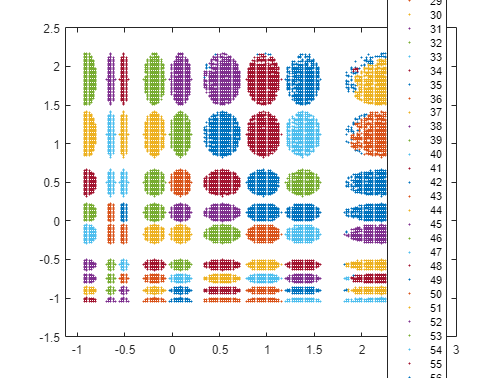



%%%第一次数据反射%%%
cleaned_data=[];
for i=1:length(VarName1)
    if cleaned(data(i,1),data(i,2)) ~= 0
        cleaned_data=[cleaned_data;data(i,:)];
    end
end

%%删除聚类中异常点
Cleaned_data=[];
clustering1=[zscore(cleaned_data(:,1)),zscore(cleaned_data(:,2))];
idx1 = dbscan(clustering1,0.03,10);
gscatter(clustering1(:,1),clustering1(:,2),idx1);

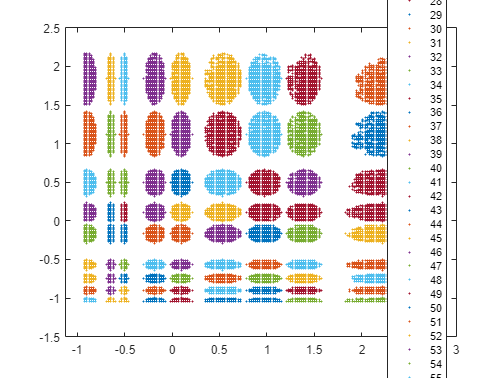

for i=1:length(idx1)
    if idx1(i,1)~=-1 && idx1(i,1)~=82 && idx1(i,1)~=83 && idx1(i,1)~=84
        Cleaned_data=[Cleaned_data;cleaned_data(i,:)];        
    end
end
FirstD2Cleand=length(Cleaned_data)/length(data);
Clustering1=[zscore(Cleaned_data(:,1)),zscore(Cleaned_data(:,2))];
Idx1 = dbscan(Clustering1,0.03,10);
gscatter(Clustering1(:,1),Clustering1(:,2),Idx1);

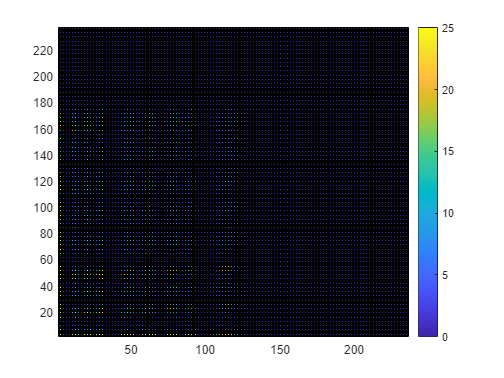

cleaned_data=[Cleaned_data,Idx1];

%%%第二次数据清洗%%%






%%%第二次数据清洗%%%

VarName1=cleaned_data(:,3);
VarName2=cleaned_data(:,4);
VarName3=cleaned_data(:,1);
VarName4=cleaned_data(:,2);
peakdata(:,1)=peakdata(:,3);
peakdata(:,2)=peakdata(:,4);
midu=[];
m=0;
zuobiao=[VarName1,VarName2];
for i=1:length(X)
    for j=1:length(X)
        for k=1:length(VarName1)
            if zuobiao(k,1)-i==0 && zuobiao(k,2)-j==0
                m=m+1;
            end
        end
        row=[i j m];
        midu=[midu;row];
        m=0;
    end
end
juzhen=zeros(237);
k=1;
for i=1:237
    for j=1:237
        juzhen(i,j)=midu(k,3);
        k=k+1;
    end
end

%%%数据清洗%%%


cleaned=zeros(237);
for i=2:8
    for j=2:8
        a=min((peakdata(i+1,1)-peakdata(i,1)),(peakdata(i,1)-peakdata(i-1,1)))/2-1;
        b=min((peakdata(j+1,2)-peakdata(j,2)),(peakdata(j,2)-peakdata(j-1,2)))/2-1;
        if a>b
            c=sqrt(a^2-b^2);
            for m=1:237
                for n=1:237
                    distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(j,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(j,2))^2);
                    if distance<=2*a
                        cleaned(m,n)=juzhen(m,n);

                    end
                end
            end
        end

        if a<=b
            c=sqrt(b^2-a^2);
            for m=1:237
                for n=1:237
                    distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(j,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(j,2)-c)^2);
                    if distance<=2*b
                        cleaned(m,n)=juzhen(m,n);
                    end
                end
            end
        end
    end
end

%bianjie zuo
for i=2:8
    a=min((peakdata(i+1,1)-peakdata(i,1)),(peakdata(i,1)-peakdata(i-1,1)))/2-1;
    b1=(peakdata(2,2)-peakdata(1,2))/2-1;
    b2=(peakdata(9,2)-peakdata(8,2))/2-1;
    if a>b1
        c=sqrt(a^2-b1^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(1,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(1,2))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b1
        c=sqrt(b1^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(1,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(1,2)-c)^2);
                if distance<=2*b1
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie you
    if a>b2
        c=sqrt(a^2-b2^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)+c))^2+(n-peakdata(9,2))^2)+sqrt((m-(peakdata(i,1)-c))^2+(n-peakdata(9,2))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b2
        c=sqrt(b2^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((m-(peakdata(i,1)))^2+(n-peakdata(9,2)+c)^2)+sqrt((m-(peakdata(i,1)))^2+(n-peakdata(9,2)-c)^2);
                if distance<=2*b2
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie xia
    a=min((peakdata(i+1,2)-peakdata(i,2)),(peakdata(i,2)-peakdata(i-1,2)))/2-1;
    b1=(peakdata(2,1)-peakdata(1,1))/2-1;
    b2=(peakdata(9,1)-peakdata(8,1))/2-1;
    if a>b1
        c=sqrt(a^2-b1^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)+c))^2+(m-peakdata(1,1))^2)+sqrt((n-(peakdata(i,2)-c))^2+(m-peakdata(1,1))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b1
        c=sqrt(b1^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)))^2+(m-peakdata(1,1)+c)^2)+sqrt((n-(peakdata(i,2)))^2+(m-peakdata(1,1)-c)^2);
                if distance<=2*b1
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    %bianjie shang
    if a>b2
        c=sqrt(a^2-b2^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)+c))^2+(m-peakdata(9,1))^2)+sqrt((n-(peakdata(i,2)-c))^2+(m-peakdata(9,1))^2);
                if distance<=2*a
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
    if a<=b2
        c=sqrt(b2^2-a^2);
        for m=1:237
            for n=1:237
                distance=sqrt((n-(peakdata(i,2)))^2+(m-peakdata(9,1)+c)^2)+sqrt((n-(peakdata(i,2)))^2+(m-peakdata(9,1)-c)^2);
                if distance<=2*b2
                    cleaned(m,n)=juzhen(m,n);
                end
            end
        end
    end
end
%sijiao
a1=(peakdata(2,1)-peakdata(1,1))/2-1;
a2=(peakdata(9,1)-peakdata(8,1))/2-1;
b1=(peakdata(2,2)-peakdata(1,2))/2-1;
b2=(peakdata(9,2)-peakdata(8,2))/2-1;
c=sqrt(a1^2-b1^2);
for m=1:237
    for n=1:237
        distance=sqrt((m-(peakdata(1,1)+c))^2+(n-peakdata(1,2))^2)+sqrt((m-(peakdata(1,1)-c))^2+(n-peakdata(1,2))^2);
        if distance<=2*a1
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
c=sqrt(b2^2-a1^2);
for m=1:237
    for n=1:237
        distance=sqrt((m-(peakdata(1,1)))^2+(n-peakdata(9,2)+c)^2)+sqrt((m-(peakdata(1,1)))^2+(n-peakdata(9,2)-c)^2);
        if distance<=2*b2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end

c=sqrt(a2^2-b1^2);
for m=1:237
    for n=1:237
        distance=sqrt((n-(peakdata(1,2)))^2+(m-peakdata(9,1)+c)^2)+sqrt((n-(peakdata(1,2)))^2+(m-peakdata(9,1)-c)^2);
        if distance<=2*a2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
c=sqrt(b2^2-a2^2);
for m=1:237
    for n=1:237
        distance=sqrt((n-(peakdata(9,2)+c))^2+(m-peakdata(9,1))^2)+sqrt((n-(peakdata(9,2)-c))^2+(m-peakdata(9,1))^2);
        if distance<=2*b2
            cleaned(m,n)=juzhen(m,n);
        end
    end
end
z=[];
k=1;
[x,y] = meshgrid(1:1:237);
for i=1:237
    for j=1:237
        if cleaned(i,j)>25
            z(i,j)=25;
        else
            z(i,j)=cleaned(i,j);
        end
    end
end
figure(1);
pcolor(x,y,z);
colorbar

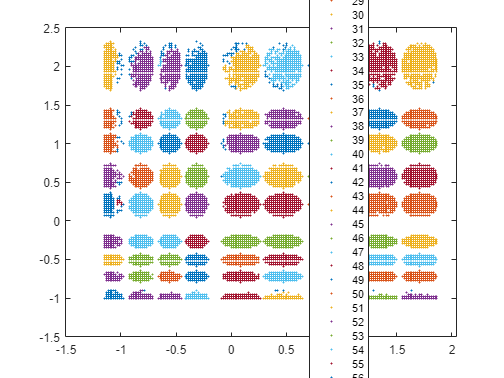



%%%第二次数据反射%%%
second_cleaned_data=[];
for i=1:length(VarName1)
    if cleaned(cleaned_data(i,3),cleaned_data(i,4)) ~= 0
        second_cleaned_data=[second_cleaned_data;cleaned_data(i,:)];
    end
end

%%删除聚类中异常点
Cleaned_data=[];
clustering2=[zscore(second_cleaned_data(:,3)),zscore(second_cleaned_data(:,4))];
idx2 = dbscan(clustering2,0.032,10);
gscatter(clustering2(:,1),clustering2(:,2),idx2);

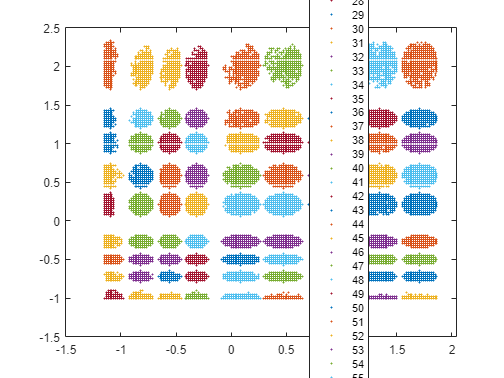

for i=1:length(idx2)
    if idx2(i,1)~=-1 && idx2(i,1)~=82 && idx2(i,1)~=83 && idx2(i,1)~=84 && idx2(i,1)~=85
        Cleaned_data=[Cleaned_data;second_cleaned_data(i,:)]; 
    end
end
SecondD2Cleand=length(Cleaned_data)/length(data);
Clustering2=[zscore(Cleaned_data(:,3)),zscore(Cleaned_data(:,4))];
Idx2 = dbscan(Clustering2,0.032,10);
gscatter(Clustering2(:,1),Clustering2(:,2),Idx2);

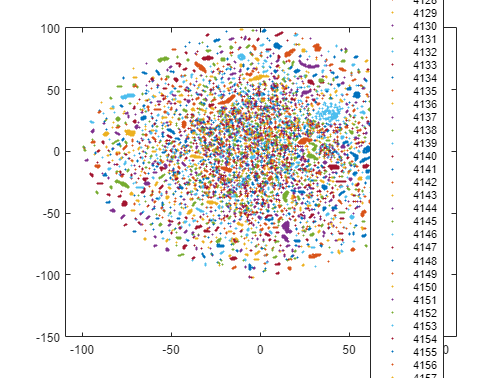

second_cleaned_data=[Cleaned_data,Idx2];

%%%降维%%%

X = second_cleaned_data;
label=[second_cleaned_data(:,5)*100+second_cleaned_data(:,6)];

decodedData = X(:,1:4); % 创建一个新的矩阵用于存放解码后的数据
yingshe=tabulate(Untitled(:,2));
yingshe=yingshe(:,1);
% 对每个元素进行解码
for i = 1:4
    for j = 1:length(X)
        % 将序数编码映射回原始值
        decodedData(j,i) = yingshe(X(j,i));
    end
end


Y=tsne(decodedData);
gscatter(Y(:,1),Y(:,2),label)